**Discriminative fungi sequences.** First load the theory. This can be generate via hca/run_theory_generate

addpath(genpath('/home/avesta/albertas/reps/hca'))
addpath(genpath('/home/avesta/albertas/reps/discriminative_sequences'))

% run against database_fungi for semi-realistic barcodes
thryName = '/export/scratch/albertas/download_dump/fungi/single/theoryOutput/theoryGen_0.34_110_300_0_2024-05-06_12_56_25_session.mat';
% thryName = 'C:\Users\Lenovo\postdoc\Chalmers\8_other\yeast_mappability\theoryGen_0.34_110_300_0_2024-05-06_12_56_25_session.mat';

import Core.load_theory_structure;
[theoryStruct,sets] = load_theory_structure(0.22,[],[],thryName);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 30).



for i=1:length(theoryStruct)
    theoryStruct(i).rawBitmask = ones(1,length(  theoryStruct(i).rawBarcode ));
end
% todo: maybe don't add extra psf?
w = 200;
wmin = 600;


% remove empty theories and the ones shorter than some minimum length wmin
theoryStruct(arrayfun(@(x) isempty(theoryStruct(x).rawBarcode),1:length(theoryStruct))) = [];
theoryStruct = theoryStruct(find([theoryStruct.length]>wmin));


nmpx = 110; %nm/px
psf = 300; %nm

Extract the names of relevant sequences. For now two cases,  'Candida albicans' and '[Candida] auris'. By default, we ran Candida albicans. This shows that there are 8 sequences

import Core.Discriminative.extract_species_name;
[uniqueSpeciesNames,idSpecies] = Core.Discriminative.extract_species_name({theoryStruct.name});

% length(find(cellfun(@(x) contains(x,'Candida'),{theoryStruct.name})))/length({theoryStruct.name})
seqNameToTest = 'Candida albicans';
% seqNameToTest = '[Candida] auris';

idSeq = find(cellfun(@(x) isequal(x,seqNameToTest),uniqueSpeciesNames));
allSeq = find(idSpecies==idSeq);
numel(allSeq)

ans = 8

{theoryStruct(allSeq).name}' % chromosomes are ordered like this

ans = 8×1 cell array
    {'>CP128823.1 Candida albicans strain SC5314 chromosome 1'}
    {'>CP128824.1 Candida albicans strain SC5314 chromosome R'}
    {'>CP128825.1 Candida albicans strain SC5314 chromosome 2'}
    {'>CP128826.1 Candida albicans strain SC5314 chromosome 3'}
    {'>CP128827.1 Candida albicans strain SC5314 chromosome 4'}
    {'>CP128828.1 Candida albicans strain SC5314 chromosome 5'}
    {'>CP128829.1 Candida albicans strain SC5314 chromosome 6'}
    {'>CP128830.1 Candida albicans strain SC5314 chromosome 7'}



chr = cellfun(@(x) x(end),{theoryStruct(allSeq).name}','un',false);

Relevant sequences with noise saved in a txt barA.txt and barC.txt

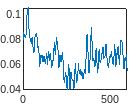

CCmax = 0.7;

%% Create a new vector from relevant theories
thryToCalc = theoryStruct(allSeq);

% thryToCalc = theoryStruct(allSeq(1:7));

% only forward 
tempCell = cell(1, 2*numel(thryToCalc)); % 1 is forward 2 is nan
tempCell(1:2:end) = {thryToCalc(:).rawBarcode};
tempCell(2:2:end) = {NaN};

% Concatenate the cell array into a single vector
vecConcat = cat(2, tempCell{:});
% convert vec to integers for simpler calculation
newvecA = round((vecConcat-min(vecConcat))/(max(vecConcat)-min(vecConcat))*256);
writematrix(newvecA,'barC.txt','Delimiter',' ');


% simple rand procedure: first fix the sRand based on similarity to the
% beginning of the sequence. We need to do this for a few random regions
% along the genome in order to get close to average CCmax in practice
N = 100;
thrId = 1;
sRandV = zeros(1,N);
for i=1:N
    rb = imgaussfilt(normrnd(0,1,1,w),psf/nmpx);
    stPos = randi(length(tempCell{thrId})-w+1,1); % starting pos on thry;
    % stPos = 5000;
    x = 0.1;
    fz = @(x) zscore( tempCell{thrId}(stPos:stPos+w-1),1)*zscore( tempCell{thrId}(stPos:stPos+w-1)+x*rb,1)'/w- CCmax;
    sRandV(i) = fzero(@(x) fz(x), [0 1]);
end
sRand = mean(sRandV,'omitnan'); % sRand for this level of noise

% now add to tempCell
for i=1:2:numel(tempCell)
    tempCell{i} = tempCell{i}+sRand*imgaussfilt(normrnd(0,1,1,length(tempCell{i})),psf/nmpx);
end


% Concatenate the cell array into a single vector
vecConcat = cat(2, tempCell{:});

% convert vec to integers for simpler calculation
newvecA = round((vecConcat-min(vecConcat))/(max(vecConcat)-min(vecConcat))*256);

writematrix(newvecA,'barA.txt','Delimiter',' ');

nanIndices = find(isnan(newvecA));

% Preallocate memory
indexes = cell(1,numel(nanIndices));
% Split the vector based on NaN delimiters
for i = 1:numel(nanIndices) % every two, since doesn't matter if we look at forward or reverse
    if i == 1
        indexes{i} = [1 nanIndices(i)-1];
    else
        indexes{i}  = [nanIndices(i-1)+1 nanIndices(i)-1];
    end
end

figure,plot(tempCell{1}(1:600))

In the same way, save all the theories into barB.txt. Note, we here save all the theories except the relevant theory. This will allow us to get the CC score for "best of the rest" theories.

Now compare to the other theories. We compare noisified ground truth theory to all other theories, and also ground truth theory to itself (without noise). This gives us MP and MPI vectors. barA vs barB is the one that takes longer time since barB is a larger database. Shoud take less than a minute on the machine though.

numWorkers = 30;
import Core.get_second_best_score;
[indexesT,restOfTheories] = get_second_best_score(idSpecies,idSeq,theoryStruct,wmin,numWorkers);

Elapsed time is 40.435271 seconds.


% 
% %% For rest of the theories
% restOfTheories = find(idSpecies~=idSeq);
% thryToCalc = theoryStruct(idSpecies~=idSeq);
% 
% % thryToCalc = theoryStruct(1:100);
% tempCell = cell(1, 4*numel(thryToCalc)); % 1 is forward, 3 is reverse, 2 and 4 is nan
% tempCell(1:4:end) = {thryToCalc(:).rawBarcode};
% tempCell(3:4:end) = cellfun(@(x) fliplr(x),{thryToCalc(:).rawBarcode},'un',false);
% tempCell(2:2:end) = {NaN};
% % Concatenate the cell array into a single vector
% vecConcat = cat(2, tempCell{:});
% 
% % convert vec to integers for simpler calculation
% newvecB = round((vecConcat-min(vecConcat))/(max(vecConcat)-min(vecConcat))*256);
% 
% nanIndices = find(isnan(newvecB));
% 
% % Preallocate memory
% indexesT = cell(1,numel(nanIndices)/2);
% % Split the vector based on NaN delimiters
% for i = 1:numel(nanIndices) % every two, since doesn't matter if we look at forward or reverse
%     if i == 1
%         indexesT{i} = [1 nanIndices(i)-1];
%     else
%         indexesT{i}  = [nanIndices(i-1)+1 nanIndices(i)-1];
%     end
% end
% 
% 
% writematrix(newvecB','barB.txt','Delimiter',' '); 


com= strcat(['SCAMP --window=' num2str(wmin) ' --input_a_file_name='...
    fullfile(pwd,'barA.txt') ' --input_b_file_name=' ...
    fullfile(pwd,'barC.txt') ' --num_cpu_workers=' num2str(numWorkers) ' --no_gpu --output_pearson --print_debug_info'...
    ' --output_a_file_name=' 'bar_mpC' ...
    ' --output_a_index_file_name=' 'bar_indexC']);

tic
[a,val ] = system(com);
toc

Elapsed time is 0.142610 seconds.


Now load output

     
fid = fopen('bar_mp');
raw2 = textscan(fid, '%s ');
fclose(fid);
nonanValues = cellfun(@(x) x(1)~='-',raw2{1});
mp1 = nan(length(nonanValues),1);
mp1(nonanValues) = sscanf(sprintf(' %s',raw2{1}{nonanValues}),'%f');

mpI1 = importdata('bar_index');

fid = fopen('bar_mpC');
raw2 = textscan(fid, '%s ');
fclose(fid);
nonanValues = cellfun(@(x) x(1)~='-',raw2{1});
mp1C = nan(length(nonanValues),1);
mp1C(nonanValues) = sscanf(sprintf(' %s',raw2{1}{nonanValues}),'%f');

% fid = fopen('bar_mpCnonoise');
% raw2 = textscan(fid, '%s ');
% fclose(fid);
% nonanValues = cellfun(@(x) x(1)~='-',raw2{1});
% mp1Cnonoise = nan(length(nonanValues),1);
% mp1Cnonoise(nonanValues) = sscanf(sprintf(' %s',raw2{1}{nonanValues}),'%f');




Now, in case the best second score is to the wrong theory, we havent saved in the mp1 the second best score (Since same positions can have best score to multiple different locations. First we extract the best theory

[bestValue,bestLoc] = max(mp1);
badVals = mp1-mp1C >= 0; % just take the theories that match better to other theory than given. Actual FP is lower, but this is a good indicator

allBad = mpI1(find(badVals))+1;

try
if ~isempty(allBad)
    ix=773;
    bestThry = find(cellfun(@(x) x(1)<=allBad(ix) && x(2) > allBad(ix),indexesT));


    thries = arrayfun(@(y) find(cellfun(@(x) x(1)<=y && x(2) > y,indexesT)),allBad);
    % % have to go back to see which theory this is
    % bestThry = find(cellfun(@(x) x(1)<bestLoc && x(2) > bestLoc,indexesT));
    secondBestSpecies  = idSpecies(restOfTheories(thries));
    
    finalFPnames = uniqueSpeciesNames(secondBestSpecies);
    
    candidaSeq = length(find(cellfun(@(x) contains(x,'Candida'),finalFPnames)))/length(finalFPnames);
else
    candidaSeq = nan;
end
catch
    candidaSeq = nan;
end

f=figure,plot(mp1);hold on;plot(mp1C);legend({'Non-matching theories best CC','Matching theories best CC'},'location','southoutside')

f =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1640 558 560 420]
       Units: 'pixels'

  Show all properties


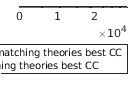

exportgraphics(f,['300kbcoverage_disc_plot_' seqNameToTest '_' num2str(sRand) '.png'],'Resolution',300)


indexes{end}(2) = length(mp1);

indMid = cellfun(@(x) (x(1)+x(2))/2,indexes);
ind1 =[ cellfun(@(x) x(1),indexes), indexes{end}(2)];


Now we plot the figure:


f = figure('Renderer', 'painters', 'Position', [100 100 1300 200])

f =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1300 200]
       Units: 'pixels'

  Show all properties


tiledlayout(5,2)
nexttile([4 2])
imagesc([mp1C-mp1 < 0.05]');colormap(gray)
cmap = [.7 .7 .7 %// light gray
    .5 .5 .5] %// white

cmap =     0.7000    0.7000    0.7000
    0.5000    0.5000    0.5000


colormap(cmap)
axis off
xlim([1 min(length(mp1),ind1(end))])

nexttile([1 2])
xticks([ind1(1:end-1) min(length(mp1),ind1(end))] )
xticklabels([] )

set(gca,'TickDir','both')

xlim([1 min(length(mp1),ind1(end))])
set(gca,'ytick',[])
box off
set(gca, 'color', 'none');
set(get(gca, 'YAxis'), 'Visible', 'off');
h = text(-3000,1,'Chr. (#)')

h =   Text (Chr. (#)) with properties:

                 String: 'Chr. (#)'
               FontSize: 10
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'left'
               Position: [-3000 1 0]
                  Units: 'data'

  Show all properties


set(h,'Rotation',0);
h2 = text(-3000,-1,'Disc. / FP (%)')

h2 =   Text (Disc. / FP (%)) with properties:

                 String: 'Disc. / FP (%)'
               FontSize: 10
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'left'
               Position: [-3000 -1 0]
                  Units: 'data'

  Show all properties


%     h3 = text(-2000,-1,'False positives (%)')

for i=1:length(indMid)
     text(indMid(i),1,num2str(i));

%     text(indMid(i),1,chr{i});
end

goodVals = mp1C-mp1 >= 0.05;
badVals = mp1-mp1C >= 0; % just take the theories that match better to other theory than given. Actual FP is lower, but this is a good indicator

nanvals = ~isnan(mp1);

mappable = zeros(1,length(indMid));
mappableFP = zeros(1,length(indMid));

for i=1:length(indMid)
    mappable(i) =sum(goodVals(indexes{i}(1):indexes{i}(2)))/ sum(nanvals(indexes{i}(1):indexes{i}(2)));
    mappableFP(i) =sum(badVals(indexes{i}(1):indexes{i}(2)))/ sum(nanvals(indexes{i}(1):indexes{i}(2)));

    text(max(indMid(i)-600,indexes{i}(1)),-1,[num2str(mappable(i)*100,3) '/'  num2str(mappableFP(i)*100,2)] )
end
%     set(h,'Rotation',0);

exportgraphics(f,['300kbcoverage_' seqNameToTest '_ccavg' num2str(CCmax) '.png'],'Resolution',300)



f = figure('Renderer', 'painters', 'Position', [100 100 1400 200])    

f =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1400 200]
       Units: 'pixels'

  Show all properties


tiledlayout(5,2)
    nexttile([4 2])
    imagesc([mp1-mp1C < 0.05]');colormap(gray)
    cmap = [.7 .7 .7 %// light gray
        .5 .5 .5] %// white

cmap =     0.7000    0.7000    0.7000
    0.5000    0.5000    0.5000


    colormap(cmap)
    axis off
        xlim([1 min(length(mp1),ind1(end))])

    nexttile([1 2])
    xticks([ind1(1:end-1) min(length(mp1),ind1(end))] )
        xticklabels([] )

    set(gca,'TickDir','both')

        xlim([1 min(length(mp1),ind1(end))])
    set(gca,'ytick',[])
    box off
    set(gca, 'color', 'none');
    set(get(gca, 'YAxis'), 'Visible', 'off');
    h = text(-2000,1,'Chr.(#)')

h =   Text (Chr.(#)) with properties:

                 String: 'Chr.(#)'
               FontSize: 10
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'left'
               Position: [-2000 1 0]
                  Units: 'data'

  Show all properties


    set(h,'Rotation',0);
    h2 = text(-2000,-1,'Disc.(%)')

h2 =   Text (Disc.(%)) with properties:

                 String: 'Disc.(%)'
               FontSize: 10
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'left'
               Position: [-2000 -1 0]
                  Units: 'data'

  Show all properties



    for i=1:length(indMid)
        text(indMid(i),1,num2str(i));
    end

    goodVals = mp1-mp1C >= 0.05;
    nanvals = ~isnan(mp1);

    mappable = zeros(1,length(indMid));
    for i=1:length(indMid)
        mappable(i) =sum(goodVals(indexes{i}(1):indexes{i}(2)))/ sum(nanvals(indexes{i}(1):indexes{i}(2)));
        text(indMid(i),-1,num2str(mappable(i)*100,2))
    end
%     set(h,'Rotation',0);

exportgraphics(f,['330kbcoverage_ccavg' num2str(CCmax) '_fp.png'],'Resolution',300)